# Activity Flow in DEM_demo_induced_fMRI.m

The purpose of this notebook is to clarify how activity spreads in the network across time when using code inspired by `DEM_demo_induced_fMRI.m` which generates "resting state" data from an AR(1) process. I'll focus on the (unobserved) neural states x. The data analysis happens at the observable BOLD level which is generated by applying the balloon model to the neural states x. The parameters for the conversion from neural states to BOLD timeseries are set and not changed by us in our simulations. Our changes to the true connectivity matrix A or the input effect matrix C only affect neural state propagation. 

## Order of operation

`DEM_demo_induced_fMRI.m` --> `spm_int_J.m` --> `spm_fx_fmri.m`

`DEM_demo_induced_fMRI.m` sets the parameters

`spm_int_J.m` loops through the time points and integrates the states using the state equation described in 

`spm_fx_fmri.m` describes how states change for each time point given the current state, the network structure and the input.

## The AR(1) process

This determines the input `u` and the observation noise `e` in `DEM_demo_induced_fMRI.m`. The third argument to the function `spm_rand_mar.m `determines the AR(p) coefficients and its lenght determines the `p` for AR(p), i.e. how much of the previous time steps is incorporated into the current time step.

In our simulations this can be controlled by `stim_options.ar_coef` where the default is set to 0.5.

How does activity look like for different values of the AR coefficient?

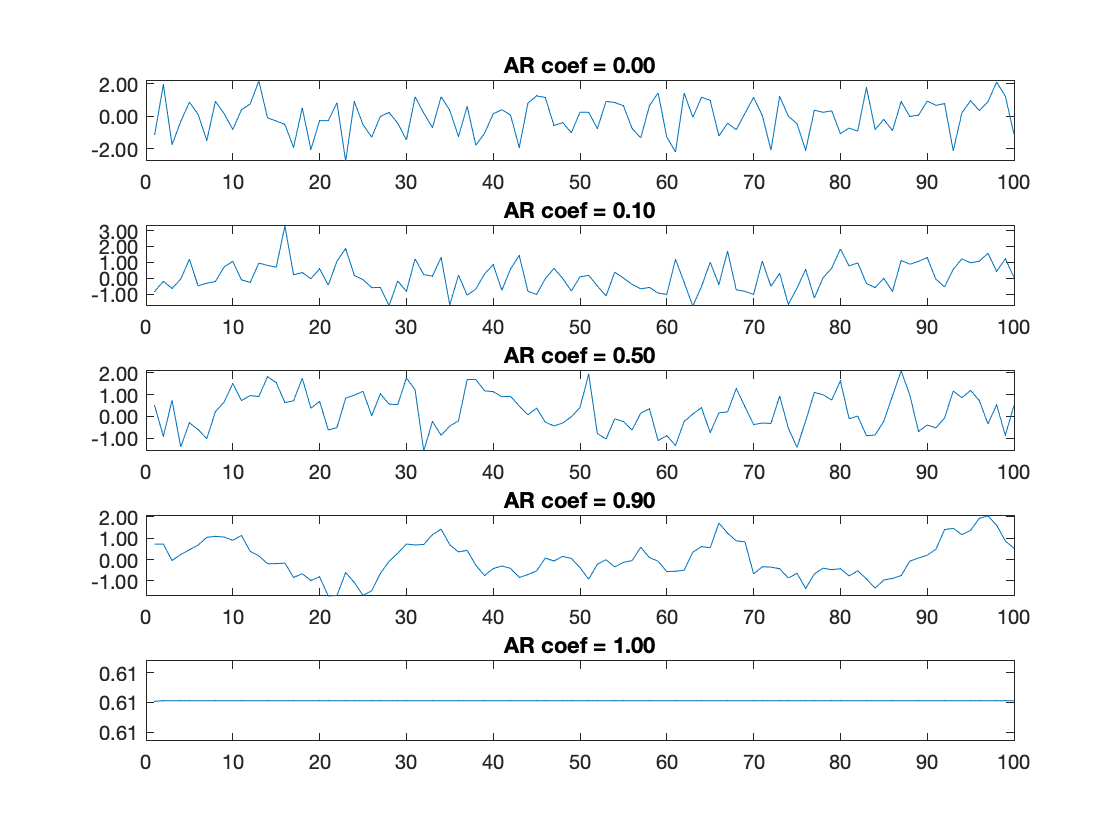

ar_coefs = [0 .1 .5 .9  1];
for i = 1:length(ar_coefs)
    tmp = spm_rand_mar(100,1,ar_coefs(i));
    subplot(length(ar_coefs), 1, i);
    plot(tmp);
    title(sprintf("AR coef = %.2f", ar_coefs(i)))
    ytickformat('%.2f')
end

## Activity flow

This is a function of EE, the curent neural state x, the C matrix that describes how each input affects each node and the input vector u(t).

More specifically the code is for the flow (i.e. `dx/dt`) that will be integrated into the current state is:

- First term `EE*x(:,1)`: network and self contribution from current **state**

- Second term `P.C*u(:)`: network and self contribution from current **inputs**

Inhibitory self-connections are encoded in the `EE` matrix. Specifically it is determined as:

where `P.A` is the user-specified connectivity matrix. Even if the diagonals of `P.A` are 0 this ensures that diagonals of `EE` are not 0 (i.e. encodes self-connections). If `P.A` is the connectivity matrix with 0 diagonals, `EE` is `P.A` with -0.5 in diagonals (i.e. inhibitory).

For resting state `P.C` is specified as a diagonal matrix with each input of `n` AR(1) processes affects each `n` nodes separately. Specifically in this case `P.C` is

## Connection to neural mass models

Previously in simulations we used the following equation to describe activity propagation:


$${\tau_i}\frac{dx_i}{dt} = -x_i(t) + g\Bigg(\sum_{j\neq i}^{N} W_{ij}\phi\big(x_j(t)\big)\Bigg) + s\phi\big(x_i(t)\big) + I_i(t)$$


This equation is written denoting the change for each node `i` instead of the matrix form used before.

Roughly, the first three terms of this equation map onto `EE*x(:1)` and the last term maps onto `P.C*u(:)`.

Self-inhibitory connections that are encoded in the diagonals of `EE`  in the SPM AR(1) framework are incorporated in the neural mass models as the sum of `-1`, `s` and $\phi$. This makes it hard to directly specify net inhibitory self-connections. It also constrains the self-connection to be to the same degreee for all nodes (i.e. there is one `s` for all nodes instead of node-specific diagonals in `EE`). For inhibitory self connections:

- either $s\le 0$

- or if $s>0$ then possible `s` values depend on $x_i \left(t\right)$and the non-linear transformation $\phi$. E.g. if $\phi =\textrm{tanh}\;x=\frac{e^{2x} -1}{e^{2x} +1}$ then we'd need $s<2x\;\frac{e^{2x} +1}{e^{2x} -1}$ for net inhibitory connections.

On the other hand the $I_i \left(t\right)$notation makes it difficult to see that the input contribution is scaled by node-specific contributions described in `P.C` in the SPM AR(1) framework.